# Eksamen 2022 efterår

clc; clear;

CP = py.importlib.import_module("CoolProp.CoolProp");


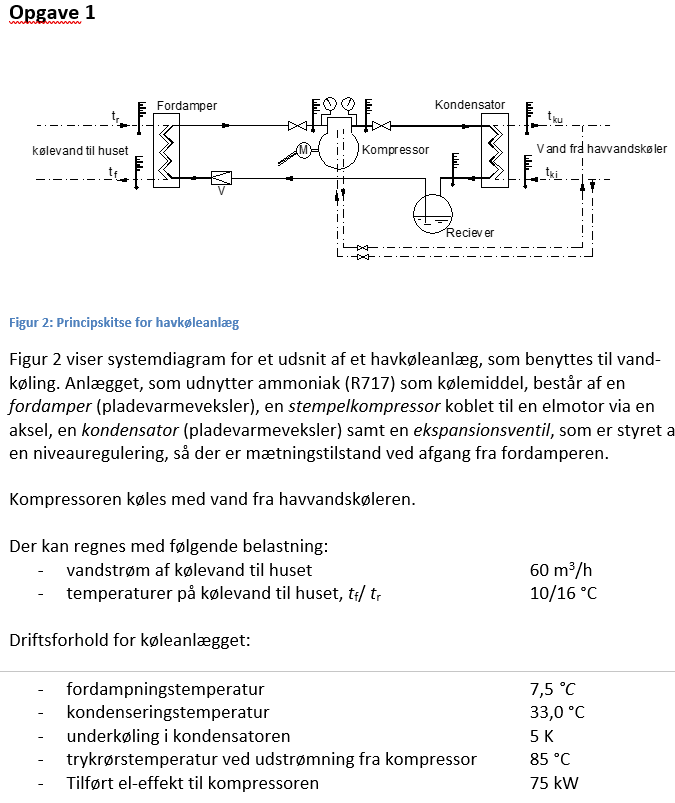

done

% Refrigerant: R717
% Values at points 1-6,15 for the selected one stage cycle
% 
% 
% Point     T     P       v        h         s     
%         [°C]  [bar] [m^3/kg]  [kJ/kg] [kJ/(kg K)]
%     1  7,499  5,637 0,223144 1468,208      5,5197
%     2 85,000 12,746 0,127915 1635,703      5,6777
%     3 84,999 12,746 0,127919 1635,703      5,6778
%     4 28,000 12,746      N/A  329,618         N/A
%     5  7,500  5,637      N/A  329,618         N/A
%     6  7,500  5,637 0,223135 1468,208      5,5197
%    15    N/A 12,746      N/A  329,618         N/A



hs = [1468.208 1635.703 329.618 1468.208]*1e3;


% Der skal findes phi0
stof = "water";
qv = 60/3600; % m3/s

tf = 16-10;
dens = CP.PropsSI("D","T", 273.15 + 10,"Q",0,stof)

dens = 999.6546

cp = CP.PropsSI("C","T", 273.15 + 16,"Q",0,stof)

cp = 4.1878e+03


phi0 = Phi0_beregner(qv, dens, cp, tf)

Formlen for phi0 bruges


$$\Phi_{0}=q_{v}\,\rho \,c_{p}\,t_{f}$$

---------------------------------------------------------
Resultatet er fundet til 418.6306 kW
---------------------------------------------------------
           Variabel           Størrelse     Enhed  
    ______________________    _________    ________

    "Phi 0"                     418.63     "kW"    
    "Volumenstrøm"            0.016667     "m3/s"  
    "Densitet"                  999.65     "kg/m3" 
    "Spec. varmekapacitet"      4187.8     "J/kg*K"
    "Temp. forskel"                  6     "K"     



phi0 = 4.1863e+05


qmr = nan;
h3 = hs(3);
h4 = hs(4);
qmr = massestrom_all(phi0, qmr, h3, h4)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: q_mR


$$sol = -\frac{\Phi }{h_{1}-h_{4}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed 
    ____________    __________    ______

    "Phi "          4.1863e+05    "W"   
    "Massestrøm"          0.37    "kg/s"
    "h3"            3.2962e+05    "J/kg"
    "h4"            1.4682e+06    "J/kg"



$$qmr = 0.3677$$


h1 = hs(1);
h2 = hs(2);

phi_komp = nan;
Pel = 75e3;
eta_is = 0.9;

Pa = Pel*eta_is;


Kompressor_Koling(phi_komp, qmr, h1, h2, Pa)

Energiligningen opstilles:


$$eq = P_{a}-\Phi_{\mathrm{kt}}+q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)=0$$

---------------------------------------------------
Hvor Pa er:


$$P_{a}=\eta_{\mathrm{motor}}\,P_{\mathrm{el}}$$

---------------------------------------------------
Der løses for: Phi_kt


$$sol = P_{a}+q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed  
    ____________    _________    ________

    "phi_komp"      5916.35      "W"     
    "Massestrøm"    0.37         "kg/s"  
    "h1"            1468208.0    "J/kg*K"
    "h2"            1635703.0    "J/kg*K"
    "Pa"            67500.0      "W"     



$$ans = 5916.0$$

h2s = 1581e3;
phi_norm = nan;

P_is = nan;
P_is = massestrom_all(P_is, qmr, h1, h2s)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          41470.75     "W"   
    "Massestrøm"    0.37         "kg/s"
    "h1"            1468208.0    "J/kg"
    "h2s"           1581000.0    "J/kg"



$$P\_is = 41470.0$$



% Den isentropiske virkningsgrad er Pa/Pis
eta_is = P_is/Pa

$$eta\_is = 0.61438150411040847689879161340219$$

COP = phi0/Pel

COP = 5.5817

## Opgave 2

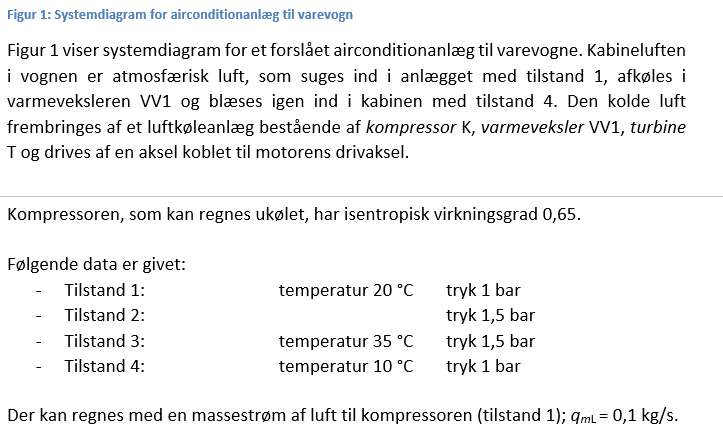

% Luft egenskaber
bar = 101325;
t0 = 273.15;

stof = "air";
t1 = 20 + t0;
p1 = 1*bar;


cp = CP.PropsSI("C","T",t0+t1,"P",p1,stof)

cp = 1.0436e+03

cv = CP.PropsSI("O","T",t0+t1,"P",p1,stof)

cv = 756.2446


% Isentrop eksponent
kap = cp/cv

kap = 1.3800


p2 = 1.5*bar;
t2s = nan;

t2s = T2s_UdFraEksponent(t2s, t1, p1, p2, kap)

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
           Variabel            Størrelse     Enhed
    _______________________    __________    _____

    "Isentropisk temp. t2s"         327.8    "K"  
    "t1"                            293.2    "K"  
    "p1"                       1.0132e+05    "Pa" 
    "p2"                       1.5199e+05    "Pa" 
    "Isentrop eksponent"              1.4    "-"  



$$t2s = 327.8$$



% Mangler funktionen fra stationær
t2 = 75.6

t2 = 75.6000

qml = 0.1; % kg/s
h1 = t1*cp

h1 = 3.0593e+05


t4 = 10+t0;
h4 = t4*cp;

phi_anlaeg = nan;

phi_anlaeg = massestrom_all(phi_anlaeg, qml, h1, h4)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed 
    ____________    __________    ______

    "Phi "              1043.6    "W"   
    "Massestrøm"           0.1    "kg/s"
    "h1"            3.0593e+05    "J/kg"
    "h4"            2.9549e+05    "J/kg"



$$phi\_anlaeg = 1044.0$$

t2 = t2 + t0;
h2 = t2*cp;

phi_komp = nan;

phi_komp = massestrom_all(phi_komp,qml, h2, h1)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed 
    ____________    __________    ______

    "Phi "              5802.4    "W"   
    "Massestrøm"           0.1    "kg/s"
    "h2"            3.6395e+05    "J/kg"
    "h1"            3.0593e+05    "J/kg"



$$phi\_komp = 5802.0$$

t3 = 35+t0;
h3 = t3*cp;

P_aksel = nan;

P_aksel = Kompressor_Koling(phi_komp, qml, h3, h4, P_aksel)

Energiligningen opstilles:


$$eq = P_{a}-\Phi_{\mathrm{kt}}+q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)=0$$

---------------------------------------------------
Hvor Pa er:


$$P_{a}=\eta_{\mathrm{motor}}\,P_{\mathrm{el}}$$

---------------------------------------------------
Der løses for: P_a


$$sol = \Phi_{\mathrm{kt}}-h_{1}\,q_{\mathrm{mR}}+h_{2}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed  
    ____________    _________    ________

    "phi_komp"      5802.35      "W"     
    "Massestrøm"    0.1          "kg/s"  
    "h3"            321581.92    "J/kg*K"
    "h4"            295492.2     "J/kg*K"
    "P_aksel"       3193.38      "W"     



$$P\_aksel = 3193.0$$

phi_vv = nan;

phi_vv = massestrom_all(phi_vv, qml, h2, h3)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed 
    ____________    __________    ______

    "Phi "                4237    "W"   
    "Massestrøm"           0.1    "kg/s"
    "h2"            3.6395e+05    "J/kg"
    "h3"            3.2158e+05    "J/kg"



$$phi\_vv = 4237.0$$

Energiligningen opstilles:


$$eq = -\frac{q_{\mathrm{mR}}\,\left(h_{1}-h_{\mathrm{2s}}\right)}{P_{a}}=\eta_{\mathrm{is}}$$

---------------------------------------------------
Hvor P_is er:


$$41470.751527452572190668433904648=q_{\mathrm{mR}}\,\left(h_{\mathrm{2s}}-h_{1}\right)$$

---------------------------------------------------
Der løses for: P_a


$$sol = -\frac{h_{1}\,q_{\mathrm{mR}}-h_{\mathrm{2s}}\,q_{\mathrm{mR}}}{\eta_{\mathrm{is}}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
            Variabel            Størrelse      Enhed  
    ________________________    __________    ________

    "Phi isentrop"                   -2609    "W"     
    "Massestrøm"                       0.1    "kg/s"  
    "h3"                        3.2158e+05    "J/kg*K"
    "h4"                        2.9549e+05    "J/kg*K"
    ""                             -4013.8    "W"     
    "Isentrop virkningsgrad"          0.65    "-"     



$$ans = -4014.0$$

    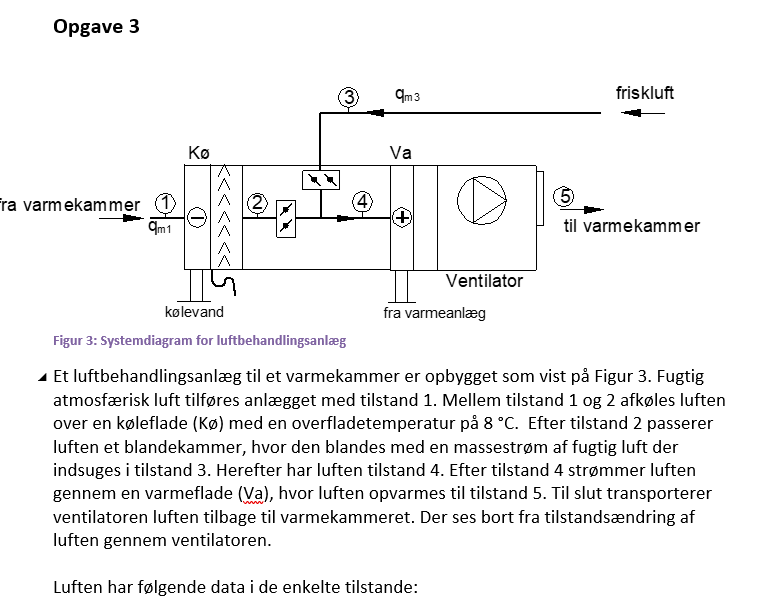

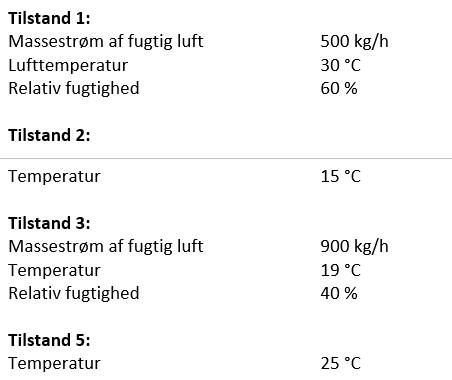

% Tilstand 1
qmf1 = 500; %kg/s
t0 = 273.15;
bar = 101325;

t1 = 30 + t0;
phi1 = 0.6;

x1 = CP.HAPropsSI("W","R",phi1,"T",t1,"P",bar)

x1 = 0.0161



qml = DryAirMassflow(qmf1, x1, "kg/hr")

Formel 7.29 bruges til at finde massestrømmen af tør luft


$${\mathrm{qm}}_{\mathrm{dry}}={\mathrm{qm}}_{\mathrm{air}}\,\frac{1}{1+x}$$

---------------------------------------------------------
Massestrømmen af tør luft er fundet til 492.0696 kg/hr


qml = 492.0696

Der kondenseres vand pga Kø < t1

qmf1 = 500;


x2 = 0.01;

udskilt_vandstrom = nan;
udskilt_vandstrom = UdskiltVandstrom(udskilt_vandstrom, qml, x1, x2)

Formel 7.41 bruges til at finde den udskilte vandstrøm
---------------------------------------------------
Der løses for: Udskildt_Vand


$$sol = q_{\mathrm{ml}}\,\left(x_{1}-x_{2}\right)$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
          Variabel           Størrelse     Enhed 
    _____________________    _________    _______

    "Udskildt vandstrøm"      3.0097      "kg/hr"
    "Tør luft massestrøm"     492.07      "kg/hr"
    "x1"                      0.0161      "kg/kg"
    "x2"                        0.01      "kg/kg"



$$udskilt\_vandstrom = 3.01$$

t1 = 30;
t_kol = 15;
qml = qml/3600;

phi_koleflade = nan;


h1 = CP.HAPropsSI("H","W",x1,"T",t1+t0,"P",bar)

h1 = 7.1365e+04

h2 = CP.HAPropsSI("H","W",x2,"T",t_kol+t0,"P",bar)

h2 = 4.0363e+04



phi_koleflade = massestrom_all(phi_koleflade, qml, h1, h2)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "           4237.6      "W"   
    "Massestrøm"       0.14      "kg/s"
    "h1"              71365      "J/kg"
    "h2"              40363      "J/kg"



$$phi\_koleflade = 4238.0$$